# Benchmark Portfolios Test File  %%% TO update SR function call

**Author: Nina Matthews**

**Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities**

**Last edit: 26/02/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resouces Used: **The MathWorks, Inc. (2019)  &  Marcos Lopez De Prado (2016) (*See reference list below)*

## **Purpose:**

This file tests:

## Data Description

The data of the 10 asset case is based on the simulated data that was generated in De Prodo's python code chunk that he defined in his 2016 paper. However, in the subsequent years, Python made a fundamental change in how their random generator functions work so the data was not fully retrievable. This issue was overcome by sourcing the data from Kipnis when he replicated the data in 2017 before the change was made. 

## Validation

The functions and additional code is validated by using the test data as well as output generated using the R programming language to compare output weights. The results show that both languages produce the same output, strongly suggesting that the methods are accurate. 

## Benchmarks:

### *Fn_EW() *using dummy data of a 10 asset case.

                   
$$\omega_ \mathrm{EW}=\left(\omega_1, \omega_2, \ldots, \omega_N\right), \omega_i=\frac{1}{N}$$


*********************************************************************************************************************************************************************************

Need to see if I want to add the below or not. need to rewrite equations myself as these are a combo of my old work and the MathWorks writing.

*********************************************************************************************************************************************************************************

- Inverse variance


$$$\omega \mathrm{IV}=\left(\omega_1, \omega_2, \ldots, \omega_N\right), \omega_i=\frac{\left(\sigma_{\mathrm{ii}}^{-1}\right)}{\sum_{i=1}^N \sigma_{\mathrm{ii}}^{-1}}$, where $\sigma_{\mathrm{ii}}$ are diagonal elements of the asset return covariance matrix.$$


### *Fn_Markowitz_RA()*

Markowitz portfolio optimization (maximizing return and minimizing risk with fixed risk-aversion coefficient)

For this MVO algorithm it will assume assets are fully invested and that the mean μ and the covariance Σ of the returns is known through sample estimation: ˆμ , ˆΣ. The aim is to minimise the overall portfolio risk at a fixed level of return:

                    $\omega_ \mathrm{Markowitz\_RA} = \min _{\mathbf{\omega}}\left\{\mathbf{\omega}^{\prime} \hat{\Sigma} \mathbf{\omega}\right\} \quad \text { s.t } \mathbf{\omega}^{\prime} \hat{\mathbf{\mu}}=\mathbb{E}\left[R_P\right] \text { and } \mathbf{\omega}^{\prime} \mathbf{1}=1$,


$$
$R_{\text {Mkwtz }}=\max _\omega\left\{r^{\prime} \omega-\lambda \omega^{\prime} Q \omega \mid \omega \geq 0, \sum_1^N \omega_i=1,0 \leq \omega \leq 0.1\right\}$, where $\lambda$ is the risk-aversion coefficient.$$


### *Fn_Max_SR()*

Putting the Sharpe Ratio into the MV framework we need to optimise:

$\omega_ \mathrm{MV\_SR} = \max _\omega\left(\frac{\mathbb{E}\left[R_P\right]-R_f}{\hat{\sigma}_P}\right)=\max _\omega\left(\frac{\mathbf{\omega}^{\prime} \hat{\mathbf{\mu}}-R_f}{\sqrt{\mathbf{\omega}^{\prime} \hat{\Sigma} \mathbf{\omega}}}\right) \text { s.t } \mathbf{\omega}^{\prime} \mathbf{1}=1$.

*********************************************************************************************************************************************************************************

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

% Add Test Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/TESTDATA/'));% Set source paths
% Add hrp/functions directory 
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
% Add benchmarks/functions directory 
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));
% Add Real Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

## 2. Load Data

### 2.1 HRP Test Data

The dataset is simulated that some assets are closely correlated.

cov_10_asset = readmatrix('Kipnis_covMat.csv')

cov_10_asset =     1.0006   -0.0031    0.0100   -0.0108   -0.0050    0.0088    0.9982   -0.0014   -0.0013   -0.0094
   -0.0031    1.0090    0.0086    0.0073   -0.0095    0.0130   -0.0094   -0.0153    1.0105    1.0133
    0.0100    0.0086    1.0007   -0.0006    0.0018    1.0016    0.0064    0.0019    0.0129    0.0080
   -0.0108    0.0073   -0.0006    1.0119    0.0058    0.0009   -0.0119    0.0005    0.0126    0.0096
   -0.0050   -0.0095    0.0018    0.0058    1.0058    0.0056   -0.0096    1.0086   -0.0062   -0.0079
    0.0088    0.0130    1.0016    0.0009    0.0056    1.0643    0.0044    0.0058    0.0172    0.0116
    0.9982   -0.0094    0.0064   -0.0119   -0.0096    0.0044    1.0582   -0.0068   -0.0081   -0.0162
   -0.0014   -0.0153    0.0019    0.0005    1.0086    0.0058   -0.0068    1.0748   -0.0119   -0.0137
   -0.0013    1.0105    0.0129    0.0126   -0.0062    0.0172   -0.0081   -0.0119    1.0753    1.0152
   -0.0094    1.0133    0.0080    0.0096   -0.0079    0.0116   -0.0162   -0.

### 2.2 MV Test Data (Real Asset data)

fileName = "DATA-PROCESSED-BALFUN_INVARIANT-LOGDIF_RETURNS-M-TTABLE-20070731-20230228.mat";
load(fileName)
fileName = 'DATA-PROCESSED-ASSETCL-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)

## 3. Benchmarks

### 3.1 Equally Weighted

wgtEW = eqweight(cov_10_asset)

wgtEW =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000


sum(wgtEW)

ans = 1.0000

### 3.2 HRP

Visualise data using a heatmap. Note: same profile as seen through R but the ordering is 1 to 10 descending whilst this is reversed when displayed in R.

% Display heatmap
% heatmap(cov_10_asset);

Apply our HRP function.

wgtHRP = hrpestimate(cov_10_asset);

Output confirmed against R output as well as De Prado's results in his principle paper on HRP.

### **3.3 Mean Variance MatLab functions**

% %% Sector Data
% tickersSectors = {'FINI15TR_Index', 'INDI25TR_Index','RESI20TR_Index'};
% SEC_BH_TT = BALFUN_log_diff(:, tickersSectors);
% BALFUN_log_diff = SEC_BH_TT;

Assets = M_Ret_TT;
AssetList = Assets.Properties.VariableNames;
AssetMean = table2array(varfun(@mean, Assets, 'InputVariables', @isnumeric));
AssetCovar = cov(table2array(Assets));
Rfr = geo_ave(M_Ret_TT.Cash);

p = Portfolio('AssetList', AssetList, 'RiskFreeRate', Rfr)

p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 0.0053
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 6
        AssetList: {'ALB_Index'  'FINI15_Index'  'INDI25_Index'  'RESI20_Index'  'JALSHTR_Index'  'Cash'}
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


%% Need to update this function call as the SR function was changed to be coded from 
% scratch and no longer uses Matlabs build in function
[x,retSR, rskSR] = maxsr(mu, Sigma, RFR,lb,ub)

Error using maxsr
Too many output arguments.

SR_opt_wts

SR_opt_wts =     0.1371         0    0.1720         0         0    0.6908


SR_opt_wts

SR_opt_wts =     0.1371         0    0.1720         0         0    0.6908


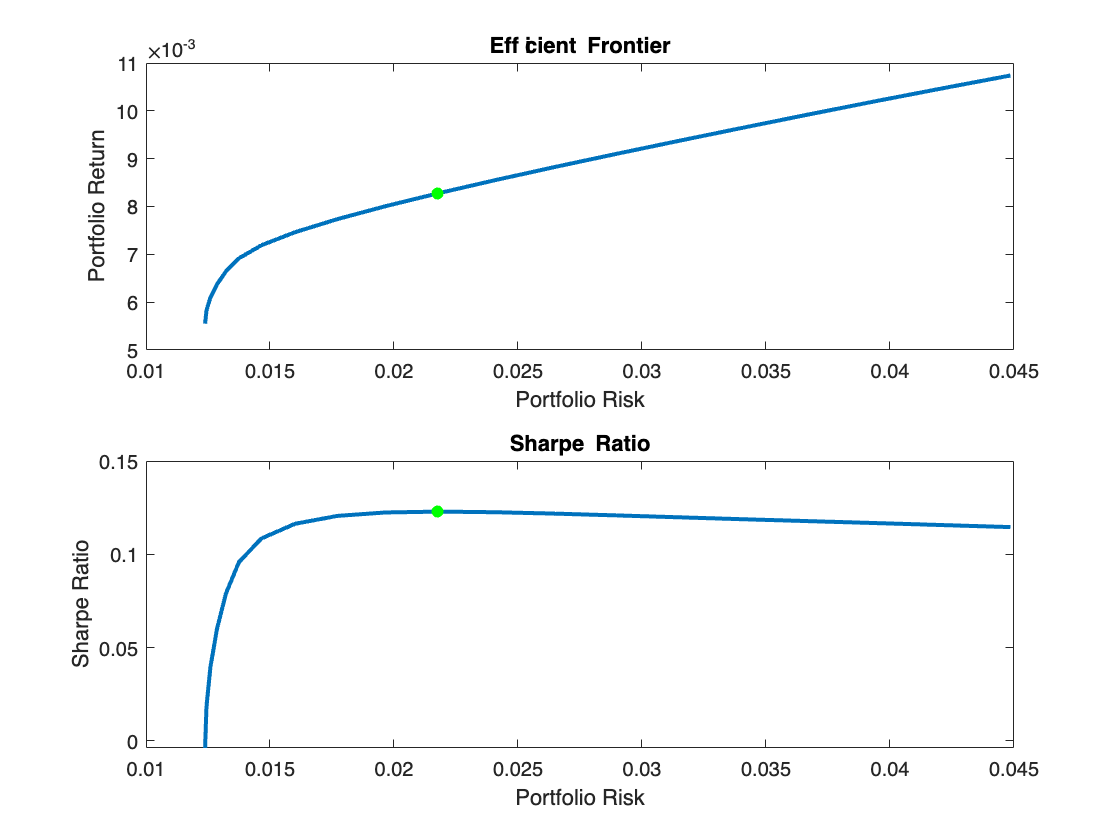

psratio = (frontier_return_vec - Rfr) ./ frontier_rsk_vec;
ssratio = (MV_SR_return - Rfr) / MV_SR_sdv;

clf;
subplot(2,1,1);
plot(frontier_rsk_vec, frontier_return_vec, 'LineWidth', 2);
hold on
scatter(MV_SR_sdv, MV_SR_return, 'g', 'filled');
title('\bfEfficient Frontier');
xlabel('Portfolio Risk');
ylabel('Portfolio Return');
hold off

subplot(2,1,2);
plot(frontier_rsk_vec, psratio, 'LineWidth', 2);
hold on
scatter(MV_SR_sdv, ssratio, 'g', 'filled');
title('\bfSharpe Ratio');
xlabel('Portfolio Risk');
ylabel('Sharpe Ratio');
hold off 

**Comparision Visualization**

Here you can visualize the resulting allocations from the two strategies. 

a = num2cell(1:nAssets);
labels = cellfun(@(x) num2str(x),a', 'UniformOutput', false);
ax1 = subplot(1,2,1);
pie(ax1,wgtHRP(wgtHRP>0),labels(wgtHRP>0))
title(ax1,'HRP Allocation','Position', [-0.05, 1.6, 0]);

ax2 = subplot(1,2,2);
pie(ax2,wgtMV(wgtMV>0),labels(wgtMV>0))
title(ax2,'Mean Variance Allocation' ,'Position', [-0.05, 1.6, 0]);
wgtTable = array2table([wgtHRP, wgtMV], 'VariableNames', {'HRP', 'MeanVariance'})

You can see that HRP produces a much more diversified allocation as compared to Mean-Variance framework. Next step, you can backtest the HRP strategy against others and extract their performance metrics. 

## Mean-variance using self defined optimisation (confirmed to work, has replaced old matlab based version)

Returns = table2array(M_Ret_TT);
% monthy sampled geometric mean of simple returns #### To match matlab
% results change the geo_ave to normal mean() fn
mu = geo_ave(Returns);
% covariance
Sigma = cov(Returns);
% No Short-selling (upper and lower bounds)
ub = ones(width(Returns),1);
lb = zeros(width(Returns),1);
% use vector below to specify set bounds eg 5% upper bound for cash
% lb = [ 0 0 0 0 0 0]; 
% ub = [ 1 1 1 1 1 0.05];


[x,retSR, rskSR] = maxsr(mu, Sigma, M_Ret_TT.Cash,lb,ub)

x =     0.1371         0    0.1720    0.0000         0    0.6908


retSR = 0.0067

rskSR = 0.0087

#### Reference

- Lopez de Prado, Marcos. "Building diversified portfolios that outperform out-of-sample", Journal of Portfolio Management, 2016 

- [https://www.mathworks.com/help/stats/hierarchical-clustering.html](https://www.mathworks.com/help/stats/hierarchical-clustering.html)

- [https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html](https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html)

- [https://en.wikipedia.org/wiki/Risk_parity](https://en.wikipedia.org/wiki/Risk_parity)